# LME on acoustic features taking the acoustic category into account

Playing around with all experimental dates manually checked so far

BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';

Loading previous data

load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls.mat'))
MicAudioGood = logical(MicAudioGood);

Get color vectors ready

% Get the color vector ready for call type
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 0 0 0];
UCT = unique(CallType);
UCTFull = UCT;
UCTFull{strcmp(UCT, 'Tr')} = 'Trill';
UCTFull{strcmp(UCT, 'Ba')} = 'Bark';
UCTFull{strcmp(UCT, 'Pi')} = 'Pitchy Call';
UCTFull{strcmp(UCT, 'Bu')} = 'Low Buzz';
UCTFull{strcmp(UCT, 'Pa')} = 'Panting';
UCTFull{strcmp(UCT, 'LT')} = 'Low Tuck';
UCTFull{strcmp(UCT, 'Sq')} = 'Squeal';
UCTFull{strcmp(UCT, 'Ra')} = 'Rattle';
UCTFull{strcmp(UCT, 'Ch')} = 'Chuckles';
UCTFull{strcmp(UCT, 'BB')} = 'Bark Buzz';
UCTFull{strcmp(UCT, 'PB')} = 'Pitchy Call Buzz';
UCTFull{strcmp(UCT, 'SB')} = 'Squeal Buzz';
UCTFull{strcmp(UCT, 'Un')} = 'Unknown';
CCT = nan(length(CallType),3);
for ct=1:length(UCT)
    CCT(contains(CallType,UCT(ct)),:) = repmat(ColorCode(ct,:),sum(contains(CallType,UCT(ct))),1);
end

% Get the color vector ready for Batname
UBat = unique(BatID);
CBat = nan(length(BatID),3);
for bat=1:length(UBat)
    CBat(contains(BatID,UBat(bat)),:) = repmat(ColorCode(bat,:),sum(contains(BatID,UBat(bat))),1);
end

% Get the color vector ready for Sex and Deafness
GD_Dir = dir('/Volumes/GoogleDrive*');
Path2RecordingTable = sprintf('/Volumes/%s/My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx', GD_Dir.name);
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(length(BatName),1);
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Female';
    end

end
USexDeaf = {'Deaf Male' 'Hearing Male' 'Deaf Female' 'Hearing Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);

% AcousticClusters = nan(size(Deaf));
% AcousticClusters(strcmp(Deaf, 'D')) = TD;
% AcousticClusters(strcmp(Deaf, 'H')) = T;
AcousticClusters = TAll;

Construct the table of PAF for statistical purposes

Tbl =  table(BatID, CallType, Sex,AcousticClusters,Deaf,log10(Duration),RMS_mean,Sal_mean,F0_mean,Spect_mean,Spect_std,Spect_kurt,Spect_skew,Spect_ent,...
    Time_mean,Time_std,Time_kurt,Time_skew,Time_ent,SpectralMean_mean,Q1_mean,Q2_mean,Q3_mean,SpectMic_mean,SpectMic_std,...
    SpectMic_kurt,SpectMic_skew,SpectMic_ent,Q1Mic_mean,Q2Mic_mean,Q3Mic_mean, 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD',...
    'Duration','RMS_mean','Sal_mean','F0_mean','Spect_mean','Spect_std','Spect_kurt','Spect_skew','Spect_ent',...
    'Time_mean','Time_std','Time_kurt','Time_skew','Time_ent','SpectralMean_mean','Q1_mean','Q2_mean','Q3_mean','SpectMic_mean','SpectMic_std',...
    'SpectMic_kurt','SpectMic_skew','SpectMic_ent','Q1Mic_mean','Q2Mic_mean','Q3Mic_mean'});
Tbl.HorD = categorical(Tbl.HorD, {'H' 'D'});
Tbl.AcousticClusters = categorical(Tbl.AcousticClusters);

## Linear mixed-effect models testing for the effect of Sex, Treatment, acoustic cluster and their interactions

The rational here is that we test for the effect of Deaf and its interaction with sex and acoustic cluster by comparing a full LME with an LME with sex and acoustic cluster only as a variable and further test for the interaction if significant by comparing the full LME with the LME omitting the interaction term

Here I am looping through all the acoustic features to apply the same LMEs on all of them 

% List of variables
AcVars = Tbl.Properties.VariableNames(6:end);

% All P-value of the tests are saved here for FDR correction in the end
Pvalue_matrix = nan(length(AcVars),4);



for vv=1:length(AcVars)
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1, '*********************     LMEs on %s   ********************\n', AcVars{vv})
    AcVar = Tbl.(sprintf('%s',AcVars{vv}));
    if contains(AcVars{vv}, 'Mic')
        Tbl_local = table(BatID(MicAudioGood), CallType(MicAudioGood), Sex(MicAudioGood),AcousticClusters(MicAudioGood),Deaf(MicAudioGood), AcVar(MicAudioGood), 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
    else
        Tbl_local = table(BatID, CallType, Sex,AcousticClusters,Deaf, AcVar, 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
    end
    Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});
    Tbl_local.AcousticClusters = categorical(Tbl_local.AcousticClusters);

    % Full Model
    lme = fitlme(Tbl_local, 'AcVar ~ Sex * HorD * AcousticClusters+ (AcousticClusters|BatID)');
    % Reduced model without deafening fixed effect
    lmeR = fitlme(Tbl_local, 'AcVar ~ Sex * AcousticClusters + (AcousticClusters|BatID)');
    TestLME_HD=compare(lmeR, lme)

    Pvalue_matrix(vv,1) = TestLME_HD.pValue(2);
    if TestLME_HD.pValue(2)<0.05
        lme
        lme2 = fitlme(Tbl_local, 'AcVar ~ Sex * HorD + HorD * AcousticClusters + (AcousticClusters|BatID)');
        TestLME_Int3=compare(lme2, lme)
        Pvalue_matrix(vv,2) = TestLME_Int3.pValue(2);
        lme3 = fitlme(Tbl_local, 'AcVar ~ Sex * HorD + AcousticClusters + (AcousticClusters|BatID)');
        TestLME_Int_HorD_AcCluster=compare(lme3, lme2)
        Pvalue_matrix(vv,3) = TestLME_Int_HorD_AcCluster.pValue(2);
        lme4 = fitlme(Tbl_local, 'AcVar ~ Sex + HorD * AcousticClusters + (AcousticClusters|BatID)');
        TestLME_Int_HorD_Sex=compare(lme4, lme2)
        Pvalue_matrix(vv,4) = TestLME_Int_HorD_Sex.pValue(2);
    end
end

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Duration   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue  
    lmeR     34    10355    10582    -5143.3                                 
    lme      46    10359    10666    -5133.4    19.832    12         0.070324


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR     34    -13984    -13757      7026                                
    lme      46    -13976    -13669    7034.1    16.279    12         0.17877


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Sal_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     34    -3341.5    -3116.1    1704.8                                
    lme      46    -3326.1    -3021.2    1709.1    8.5846    12         0.73794


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on F0_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lmeR     34    78163    78386    -39047                                  
    lme      46    78158    78460    -39033    28.739    12         0.0043064


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            5191
    Fixed effects coefficients          24
    Random effects coefficients         60
    Covariance parameters               22

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    78158    78460    -39033           78066   

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat        DF      pValue        Lower      Upper 
    {'(Intercept)'                    }         297.21     71.254       4.1712    5167    3.0797e-05     157.53     436.9
    {'Sex_M'                          }         234.78     111.01        2.115    5167       0.03448     17.156    452.41
    {'Acousti

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lme2     36    78160    78396    -39044                                 
    lme      46    78158    78460    -39033    21.374    10         0.018632


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lme3     31    78158    78361    -39048                                
    lme2     36    78160    78396    -39044    8.1848    5          0.14634


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lme4     35    78160    78390    -39045                                 
    lme2     36    78160    78396    -39044    2.8041    1          0.094024


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Spect_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lmeR     34    88128    88355    -44030                                  
    lme      46    88123    88430    -44015    29.276    12         0.0035845


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            5894
    Fixed effects coefficients          24
    Random effects coefficients         60
    Covariance parameters               22

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    88123    88430    -44015           88031   

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat       DF      pValue        Lower      Upper  
    {'(Intercept)'                    }         1569.9     118.88      13.206    5870    2.9379e-39     1336.9       1803
    {'Sex_M'                          }         46.098     187.37     0.24603    5870       0.80566    -321.21      413.4
    {'Acousti

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lme2     36    88122    88363    -44025                                 
    lme      46    88123    88430    -44015    19.847    10         0.030737


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lme3     31    88128    88336    -44033                                  
    lme2     36    88122    88363    -44025    16.057    5          0.0066841


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lme4     35    88121    88355    -44026                                 
    lme2     36    88122    88363    -44025    0.90273    1          0.34205


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Spect_std   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     34    81999    82226    -40965                                
    lme      46    82004    82312    -40956    18.334    12         0.10592


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Spect_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lmeR     34    54781    55008    -27356                                 
    lme      46    54786    55093    -27347    19.208    12         0.083639


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Spect_skew   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lmeR     34    22345    22572    -11138                                  
    lme      46    22340    22647    -11124    29.083    12         0.0038298


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            5894
    Fixed effects coefficients          24
    Random effects coefficients         60
    Covariance parameters               22

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    22340    22647    -11124           22248   

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE         tStat       DF      pValue        Lower       Upper  
    {'(Intercept)'                    }          1.6406    0.24637      6.6591    5870    3.0048e-11      1.1576     2.1236
    {'Sex_M'                          }         0.29254    0.38558     0.75871    5870       0.44806    -0.46333     1.0484
    {'A

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lme2     36    22340    22580    -11134                                 
    lme      46    22340    22647    -11124    20.245    10         0.027016


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lme3     31    22341    22548    -11139                                 
    lme2     36    22340    22580    -11134    10.817    5          0.055138


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat      deltaDF    pValue
    lme4     35    22338    22572    -11134                                 
    lme2     36    22340    22580    -11134    0.097297    1          0.7551


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Spect_ent   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR     34    -11147    -10920    5607.6                                
    lme      46    -11135    -10828    5613.6    12.048    12         0.44186


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Time_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     34    -6316.7    -6089.5    3192.3                                
    lme      46    -6308.1    -6000.8    3200.1    15.462    12         0.21713


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Time_std   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR     34    -12818    -12590    6442.8                                
    lme      46    -12806    -12499    6449.2    12.801    12         0.38369


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Time_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue 
    lmeR     34    14936    15164    -7434.2                                
    lme      46    14948    15255    -7427.8    12.683    12         0.39246


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Time_skew   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    lmeR     34    7251.9    7479.1    -3591.9                                 
    lme      46    7252.6    7559.9    -3580.3    23.299    12         0.025293


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            5894
    Fixed effects coefficients          24
    Random effects coefficients         60
    Covariance parameters               22

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    7252.6    7559.9    -3580.3          7160.6  

Fixed effects coefficients (95% CIs):
    Name                                       Estimate      SE          tStat        DF      pValue        Lower        Upper    
    {'(Intercept)'                    }           0.11234    0.030269       3.7115    5870    0.00020792     0.053006      0.17168
    {'Sex_M'                          }         -0.051607    0.045664      -1.1301    5870       0.25846     -0.1

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    lme2     36    7249.9    7490.4    -3588.9                                 
    lme      46    7252.6    7559.9    -3580.3    17.274    10         0.068523


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lme3     31    7244.7    7451.8    -3591.4                                
    lme2     36    7249.9    7490.4    -3588.9    4.8429    5          0.43535


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat      deltaDF    pValue 
    lme4     35    7247.9    7481.8      -3589                                  
    lme2     36    7249.9    7490.4    -3588.9    0.054839    1          0.81485


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Time_ent   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue  
    lmeR     34    -22273    -22046    11171                                  
    lme      46    -22269    -21962    11181     19.688    12         0.073225


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectralMean_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lmeR     34    90882    91109    -45407                                  
    lme      46    90878    91185    -45393    28.395    12         0.0048413


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            5890
    Fixed effects coefficients          24
    Random effects coefficients         60
    Covariance parameters               22

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    90878    91185    -45393           90786   

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat       DF      pValue         Lower      Upper  
    {'(Intercept)'                    }         3701.1     123.39      29.996    5866    4.8661e-184     3459.2     3942.9
    {'Sex_M'                          }         483.15     194.21      2.4878    5866       0.012883     102.42     863.88
    {'Acou

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lme2     36    90874    91114    -45401                                 
    lme      46    90878    91185    -45393    16.229    10         0.093271


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lme3     31    90881    91088    -45410                                  
    lme2     36    90874    91114    -45401    17.279    5          0.0039992


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lme4     35    90872    91106    -45401                                 
    lme2     36    90874    91114    -45401    0.14615    1          0.70224


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q1_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lmeR     34    82751    82978    -41341                                  
    lme      46    82747    83054    -41327    27.721    12         0.0060759


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            5890
    Fixed effects coefficients          24
    Random effects coefficients         60
    Covariance parameters               22

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    82747    83054    -41327           82655   

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat       DF      pValue        Lower      Upper  
    {'(Intercept)'                    }         1637.3     61.113      26.791    5866     2.87e-149     1517.5     1757.1
    {'Sex_M'                          }         220.46     96.193      2.2919    5866      0.021949     31.887     409.03
    {'Acousti

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lme2     36    82741    82981    -41334                                
    lme      46    82747    83054    -41327    14.023    10         0.17193


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lme3     31    82747    82954    -41342                                  
    lme2     36    82741    82981    -41334    16.086    5          0.0066015


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lme4     35    82742    82976    -41336                                 
    lme2     36    82741    82981    -41334    3.2401    1          0.071856


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q2_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lmeR     34    91027    91254    -45480                                  
    lme      46    91023    91331    -45466    28.054    12         0.0054327


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            5890
    Fixed effects coefficients          24
    Random effects coefficients         60
    Covariance parameters               22

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    91023    91331    -45466           90931   

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat        DF      pValue         Lower      Upper  
    {'(Intercept)'                    }         3176.3      115.6       27.478    5866    1.8251e-156     2949.7       3403
    {'Sex_M'                          }         463.56     181.84       2.5494    5866       0.010818      107.1     820.03
    {'A

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lme2     36    91016    91257    -45472                                
    lme      46    91023    91331    -45466    12.838    10         0.23285


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lme3     31    91023    91230    -45480                                 
    lme2     36    91016    91257    -45472    16.608    5          0.005306


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lme4     35    91017    91251    -45474                                 
    lme2     36    91016    91257    -45472    3.0582    1          0.080329


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q3_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lmeR     34    97236    97463    -48584                                 
    lme      46    97232    97540    -48570    27.77     12         0.005977


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            5890
    Fixed effects coefficients          24
    Random effects coefficients         60
    Covariance parameters               22

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    97232    97540    -48570           97140   

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat        DF      pValue         Lower      Upper  
    {'(Intercept)'                    }         5534.7     226.82       24.401    5866    2.4481e-125       5090     5979.3
    {'Sex_M'                          }         871.99     357.19       2.4412    5866       0.014667     171.76     1572.2
    {'A

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lme2     36    97228    97468    -48578                                
    lme      46    97232    97540    -48570    15.302    10         0.12143


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lme3     31    97236    97443    -48587                                 
    lme2     36    97228    97468    -48578    17.804    5          0.003202


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lme4     35    97226    97460    -48578                                 
    lme2     36    97228    97468    -48578    0.13472    1          0.71359


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lmeR     34    90840    91062    -45386                                  
    lme      46    90836    91135    -45372    28.286    12         0.0050231


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4936
    Fixed effects coefficients          24
    Random effects coefficients         60
    Covariance parameters               22

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    90836    91135    -45372           90744   

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat        DF      pValue        Lower      Upper  
    {'(Intercept)'                    }         3819.9     307.32        12.43    4912    6.0283e-35     3217.4     4422.4
    {'Sex_M'                          }        -1128.9     479.55      -2.3541    4912      0.018608      -2069    -188.77
    {'Acou

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lme2     36    90841    91075    -45384                                  
    lme      46    90836    91135    -45372    24.426    10         0.0065469


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lme3     31    90842    91044    -45390                                 
    lme2     36    90841    91075    -45384    11.627    5          0.040273


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lme4     35    90839    91066    -45384                                 
    lme2     36    90841    91075    -45384    0.17368    1          0.67687


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_std   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    lmeR     34    87513    87734    -43722                               
    lme      46    87521    87820    -43715    15.406    12         0.22  


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lmeR     34    58065    58286    -28998                                 
    lme      46    58066    58365    -28987    22.356    12         0.033722


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4936
    Fixed effects coefficients          24
    Random effects coefficients         60
    Covariance parameters               22

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    58066    58365    -28987           57974   

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat       DF      pValue        Lower      Upper  
    {'(Intercept)'                    }         42.008     6.1302      6.8526    4912     8.146e-12      29.99     54.025
    {'Sex_M'                          }         83.642     9.3185      8.9759    4912    3.9282e-19     65.374     101.91
    {'Acousti

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue    
    lme2     36    58076    58310    -29002                                   
    lme      46    58066    58365    -28987    29.619    10         0.00098849


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lme3     31    58071    58272    -29004                                
    lme2     36    58076    58310    -29002    4.6722    5          0.45718


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lme4     35    58076    58304    -29003                                
    lme2     36    58076    58310    -29002    2.5073    1          0.11332


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_skew   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lmeR     34    26834    27056    -13383                                 
    lme      46    26839    27138    -13373    19.87     12         0.069579


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_ent   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     34    -7076.5    -6855.4    3572.2                                
    lme      46      -7076    -6776.8      3584    23.503    12         0.02375


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4936
    Fixed effects coefficients          24
    Random effects coefficients         60
    Covariance parameters               22

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC      BIC        LogLikelihood    Deviance
    -7076    -6776.8    3584             -7168   

Fixed effects coefficients (95% CIs):
    Name                                       Estimate     SE          tStat       DF      pValue         Lower        Upper      
    {'(Intercept)'                    }          0.58911    0.023496      25.073    4912    1.1823e-130      0.54305        0.63517
    {'Sex_M'                          }        -0.097941    0.036941     -2.6513    4912       0.008044     -0.

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue   
    lme2     36    -7068.5    -6834.4    3570.3                                  
    lme      46      -7076    -6776.8      3584    27.481    10         0.0021844


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue  
    lme3     31    -7068.3    -6866.7    3565.2                                 
    lme2     36    -7068.5    -6834.4    3570.3    10.172    5          0.070498


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat      deltaDF    pValue 
    lme4     35    -7070.5    -6842.8    3570.2                                  
    lme2     36    -7068.5    -6834.4    3570.3    0.027973    1          0.86717


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q1Mic_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lmeR     34    89624    89845    -44778                                 
    lme      46    89626    89925    -44767    22.17     12         0.035659


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4932
    Fixed effects coefficients          24
    Random effects coefficients         60
    Covariance parameters               22

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    89626    89925    -44767           89534   

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat       DF      pValue        Lower      Upper  
    {'(Intercept)'                    }           4929     520.95      9.4617    4908    4.5765e-21     3907.8     5950.3
    {'Sex_M'                          }         530.57      820.7     0.64649    4908       0.51799    -1078.4     2139.5
    {'Acousti

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lme2     36    89627    89862    -44778                                 
    lme      46    89626    89925    -44767    21.305    10         0.019067


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lme3     31    89626    89827    -44782                                
    lme2     36    89627    89862    -44778    8.4306    5          0.13405


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lme4     35    89626    89854    -44778                                 
    lme2     36    89627    89862    -44778    0.58891    1          0.44284


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q2Mic_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     34    97692    97913    -48812                                
    lme      46    97704    98003    -48806    12.289    12         0.42276


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q3Mic_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR     34    1.0318e+05     1.034e+05    -51557                                
    lme      46    1.0319e+05    1.0349e+05    -51550    13.888    12         0.30795


**Now correct all comparisons for false discovery rate (True proba = p*(Num_comparisons-rank))**

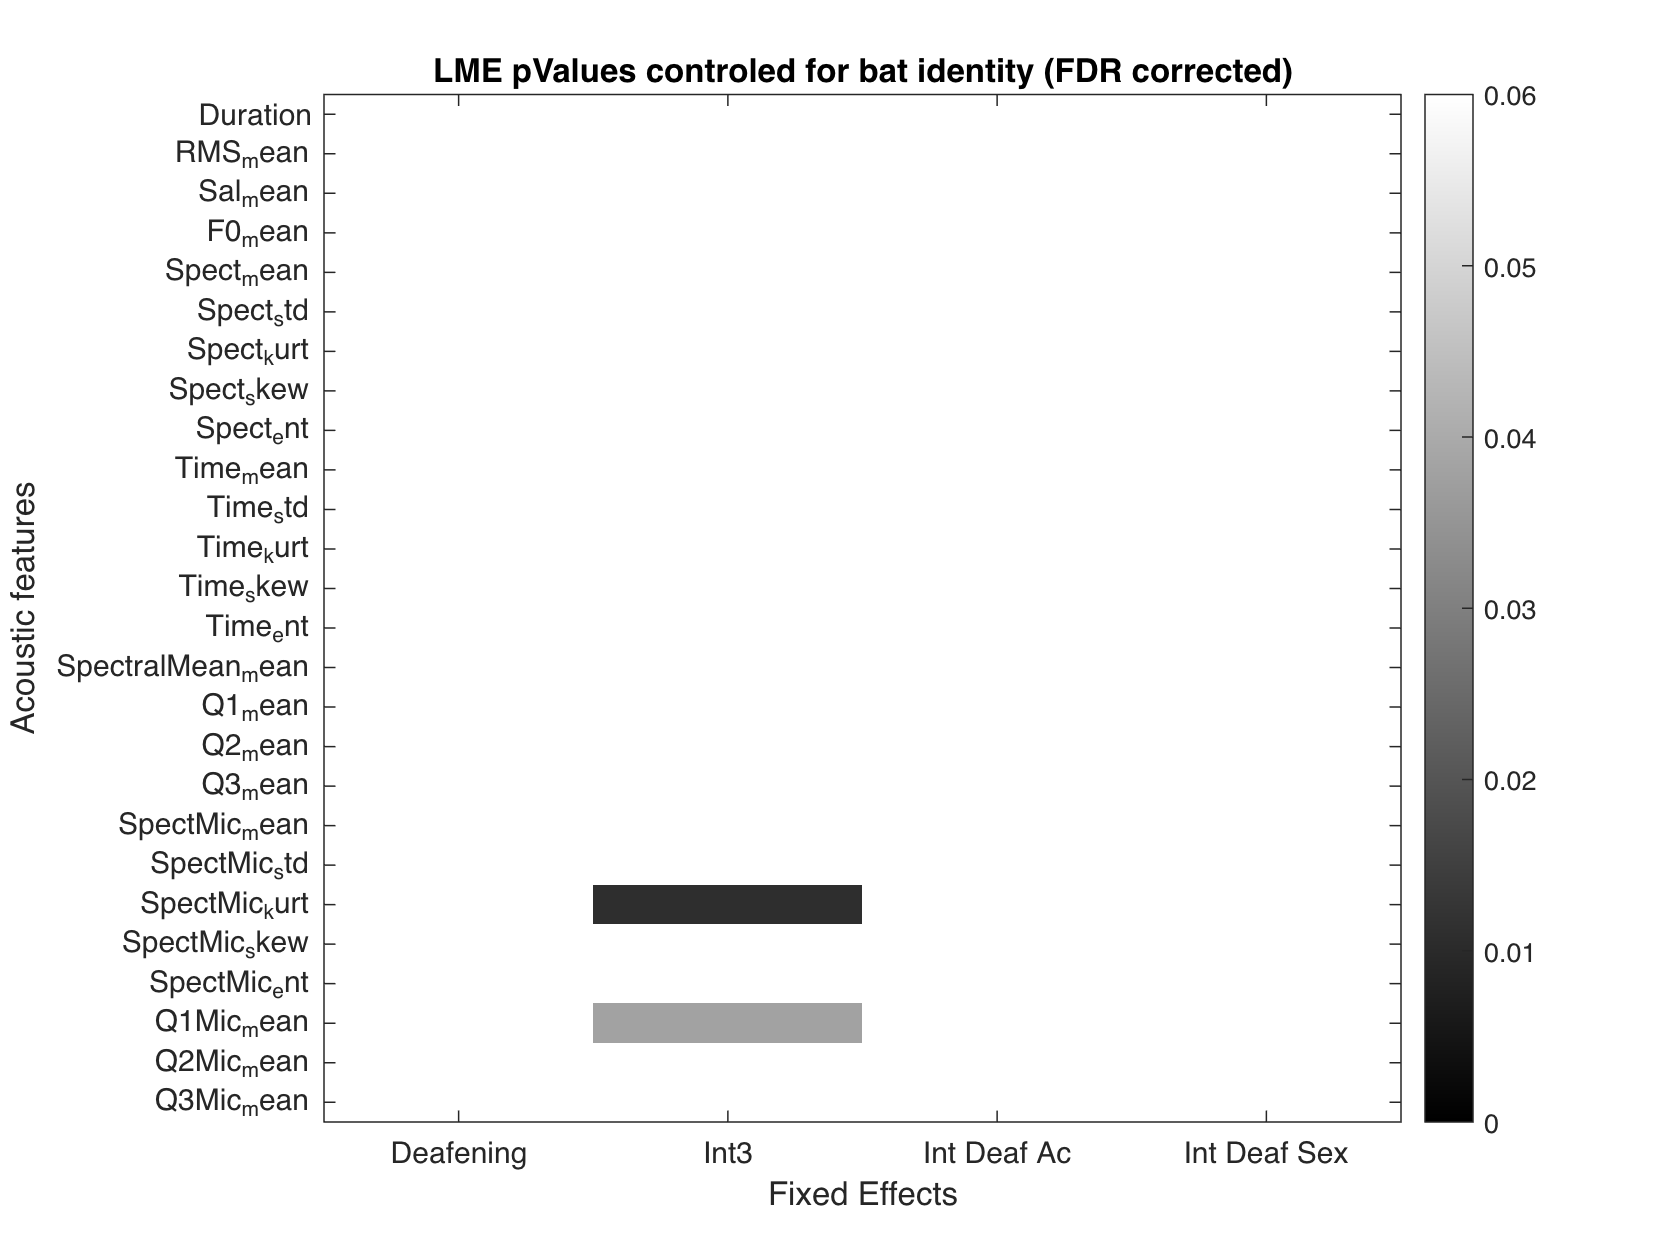

% Now correct that probability for False discovery rate (True proba =
% p*(Num_comparisons-rank))
Pvalue_vector = [Pvalue_matrix(:,1);Pvalue_matrix(:,2);Pvalue_matrix(:,3);Pvalue_matrix(:,4)];
NonNaNInd = ~isnan(Pvalue_vector);
[~,Ord]=sort(Pvalue_vector(NonNaNInd));
Ord(Ord==length(Ord)) = length(Ord)-1;
Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);
Pvalue_matrixFDR = [Pvalue_vectorFDR(1:size(Pvalue_matrix,1)) Pvalue_vectorFDR((size(Pvalue_matrix,1)+1) : 2*size(Pvalue_matrix,1)) Pvalue_vectorFDR((2*size(Pvalue_matrix,1)+1) : 3*size(Pvalue_matrix,1)) Pvalue_vectorFDR((3*size(Pvalue_matrix,1)+1) : end)];
% Pvalue_matrix4plot = Pvalue_matrix;
% Pvalue_matrix4plot(isnan(Pvalue_matrix))=1;

figure()
% tiledlayout(1,2)
% nexttile
% Im = imagesc(Pvalue_matrix4plot);
% colorbar()
% colormap(Im.Parent,'gray')
% Im.Parent.CLim = [0 0.06];
% set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
% set(gca, 'XTick', 1:4,'XTickLabel', {'Deafening' 'Int3' 'Int Deaf Ac' 'Int Deaf Sex'})
% ylabel('Acoustic features')
% xlabel('Fixed Effects')
% title('LME pValues controled for bat identity')
% nexttile
Im = imagesc(Pvalue_matrixFDR);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1:4,'XTickLabel', {'Deafening' 'Int3' 'Int Deaf Ac' 'Int Deaf Sex'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title('LME pValues controled for bat identity (FDR corrected)')

## Now let's do post-hoc LME to investigate the effect of Deafening in each acoustical category for each significant feature

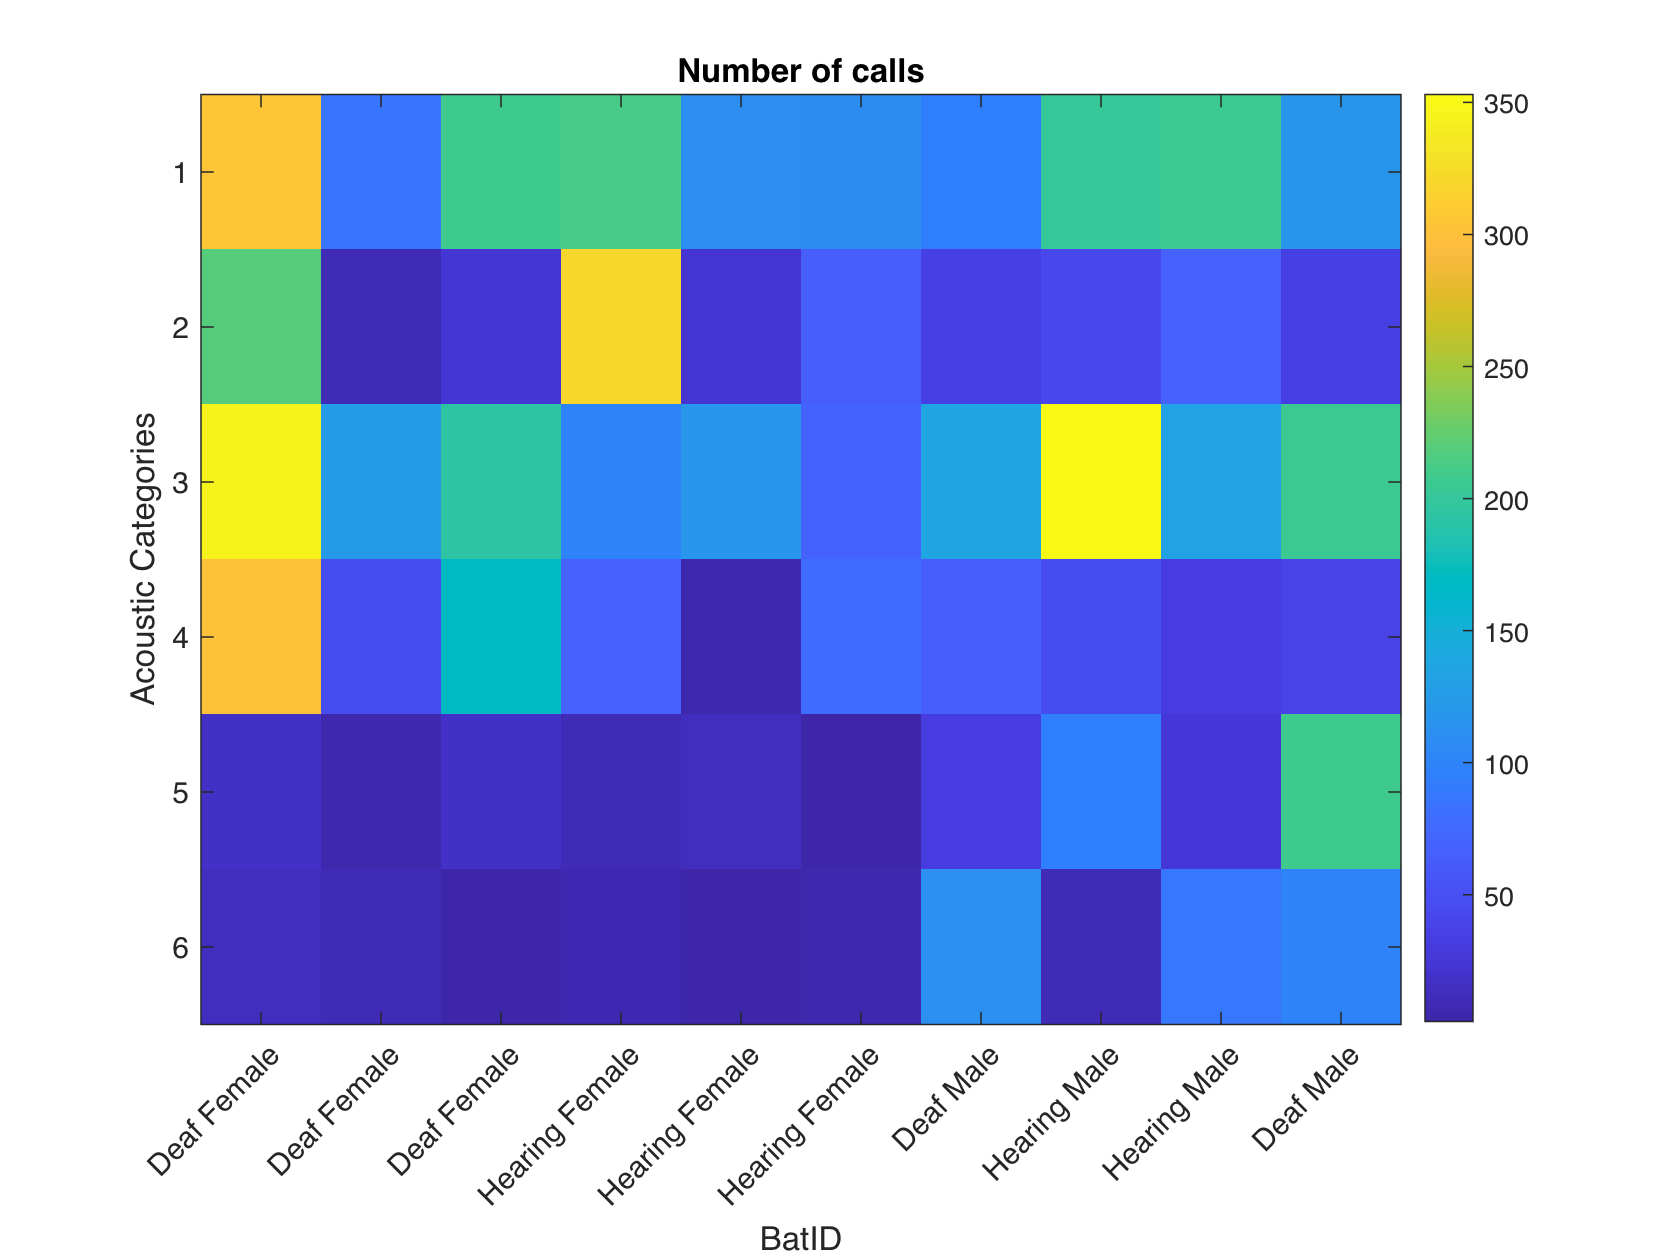

UCat = unique(AcousticClusters);
NumCalls = nan(length(UCat), length(BatName));
for bb=1:length(BatName)
    for cc=1:length(UCat)
        NumCalls(cc,bb) = sum((AcousticClusters==UCat(cc)).* strcmp(BatID, num2str(BatName(bb))));
    end
end
figure()
IM = imagesc(NumCalls);
xlabel('BatID')
ylabel('Acoustic Categories')
colorbar()
title('Number of calls')
IM.Parent.XTick = 1:length(BatName);
IM.Parent.XTickLabels=BatSexDeaf;
IM.Parent.XTickLabelRotation = 45;

Note that for categories 5 and 6 females have emitted very few of these calls -> we should probably only focus on males for these categories

Go through all acoustic categories and run an LME testing for the effect of Sex and deafening controling for BatID. Make sure that there are enough points per model for each sub-category!

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 1----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue    
    lmeR     4     17056    17077    -8523.9                                   
    lme      6     17044    17076    -8516.2    15.454    2          0.00044081


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue    
    lme2     5     17058    17084    -8523.9                                   
    lme      6     17044    17076    -8516.2    15.453    1          8.4571e-05


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1424
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    17044    17076    -8516.2          17032   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat      DF      pValue         Lower      Upper  
    {'(Intercept)' }         124.28      5.246      23.69    1420    8.0322e-105     113.99     134.57
    {'Sex_F'       }        -80.164     7.1598    -11.196    1420     6.0505e-28    -94.209    -66.119
    {'HorD_D'      }        -30.456     9.3709    -3.2501    1420      0.0011807    -48.838    -12.074
    {'Sex_F:HorD_D'}         44.618     11.319     3.9418    

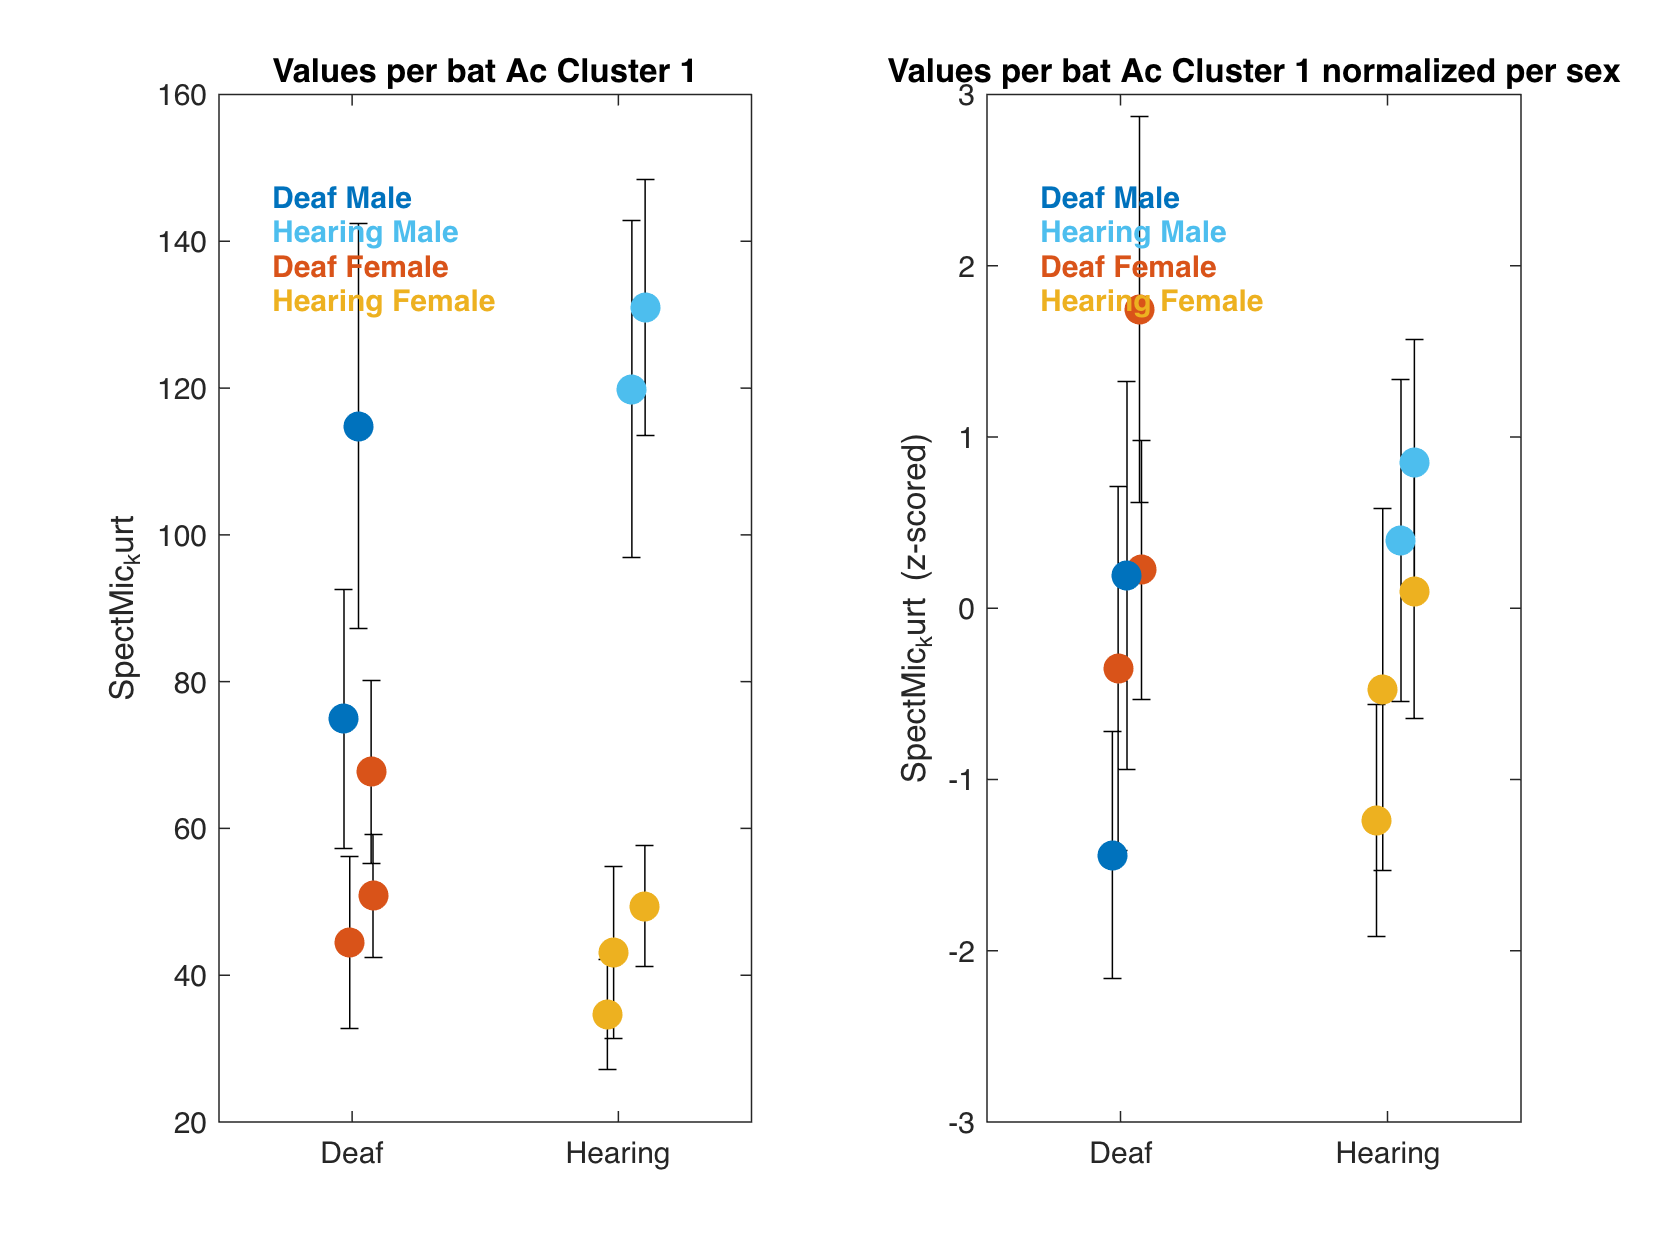

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q1Mic_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lmeR     4     26161    26182    -13076                                 
    lme      6     26164    26196    -13076    0.41338    2          0.81327


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 2----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lmeR     4     8520.2    8538.9    -4256.1                                 
    lme      6     8523.5    8551.5    -4255.8    0.68552    2          0.70981


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q1Mic_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue
    lmeR     4     13960    13978    -6975.9                               
    lme      6     13962    13990    -6974.9    2.0289    2          0.3626


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 3----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue
    lmeR     4     15610    15631    -7801                                 
    lme      6     15622    15653    -7805     -8.1002    2          1     


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q1Mic_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lmeR     4     24466    24487    -12229                                 
    lme      6     24470    24501    -12229    0.75117    2          0.68689


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 4----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue   
    lmeR     4     8718.6    8737.1    -4355.3                                  
    lme      6     8712.7    8740.5    -4350.4    9.9038    2          0.0070701


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    lme2     5       8717    8740.1    -4353.5                                 
    lme      6     8712.7    8740.5    -4350.4    6.3196    1          0.011941


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             752
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    8712.7    8740.5    -4350.4          8700.7  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat       DF     pValue        Lower      Upper  
    {'(Intercept)' }         30.086     6.7766      4.4397    748    1.0366e-05     16.783     43.389
    {'Sex_M'       }         78.958     11.887      6.6424    748    5.9372e-11     55.622     102.29
    {'HorD_D'      }        -3.5179     7.6534    -0.45965    748        0.6459    -18.543     11.507
    {'Sex_M:HorD_D'}        -40.144     15.936     -2.5192   

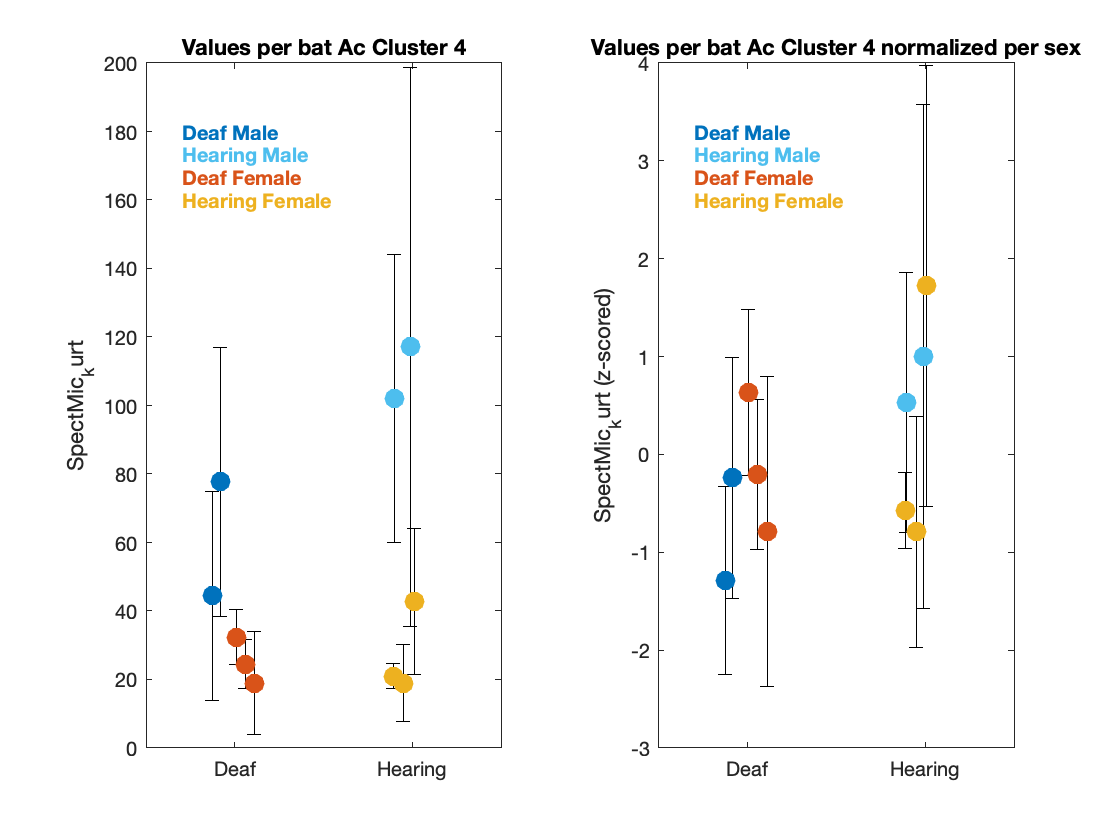

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q1Mic_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue  
    lmeR     4     13133    13151    -6562.4                                 
    lme      6     13129    13157    -6558.5    7.737     2          0.020889


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue 
    lme2     5     13128    13151    -6558.9                                
    lme      6     13129    13157    -6558.5    0.7374    1          0.39049


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             751
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    13129    13157    -6558.5          13117   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat       DF     pValue        Lower      Upper 
    {'(Intercept)' }         4245.9     368.83      11.512    747    2.4068e-28     3521.9      4970
    {'Sex_M'       }         847.65     565.34      1.4994    747        0.1342    -262.19    1957.5
    {'HorD_D'      }         1487.8     493.34      3.0158    747     0.0026499     519.32    2456.3
    {'Sex_M:HorD_D'}        -679.03     783.59    -0.86655    747    

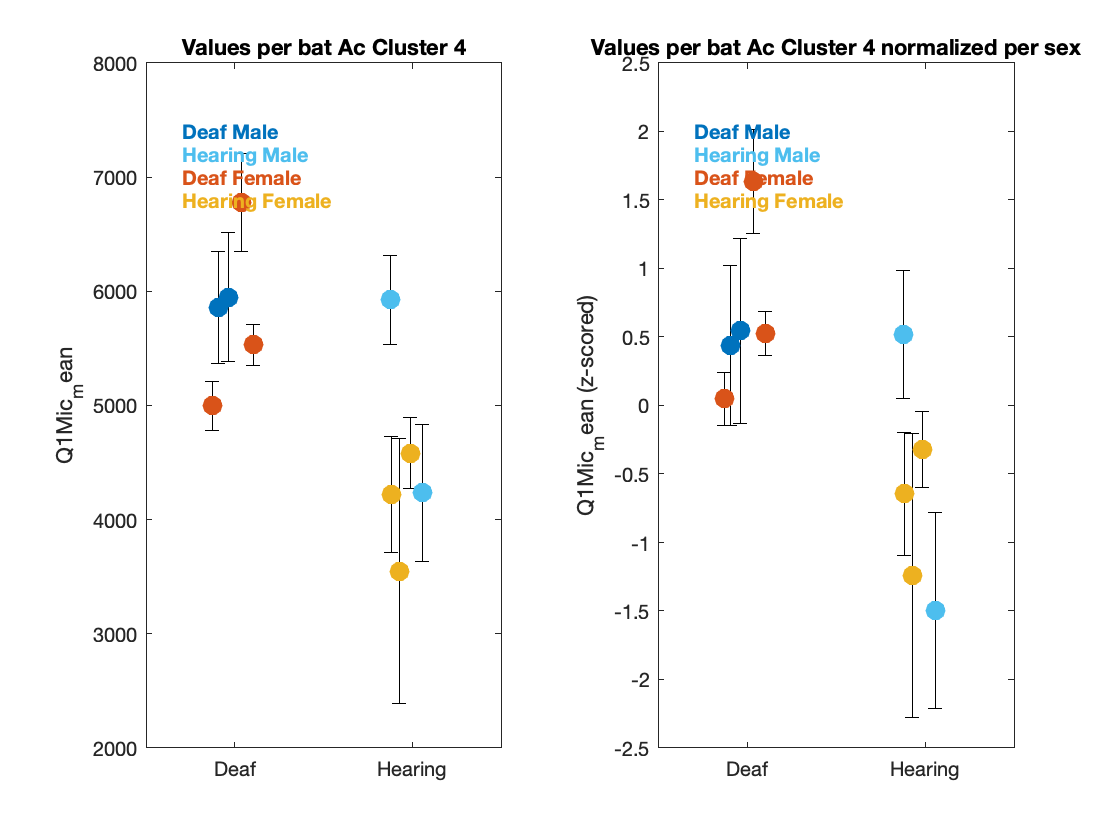

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 5----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    lmeR     4     4230.6    4246.1    -2111.3                                 
    lme      6     4227.4    4250.6    -2107.7    7.2422    2          0.026753


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue   
    lme2     5     4232.6    4251.9    -2111.3                                  
    lme      6     4227.4    4250.6    -2107.7    7.2335    1          0.0071557


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             354
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    4227.4    4250.6    -2107.7          4215.4  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat      DF     pValue        Lower      Upper  
    {'(Intercept)' }         146.89     35.236     4.1688    350    3.8639e-05     77.591     216.19
    {'Sex_F'       }        -62.023     50.053    -1.2391    350       0.21612    -160.46     36.419
    {'HorD_D'      }         -123.7     49.512    -2.4984    350      0.012932    -221.08    -26.324
    {'Sex_F:HorD_D'}         226.38     68.801     3.2903    350 

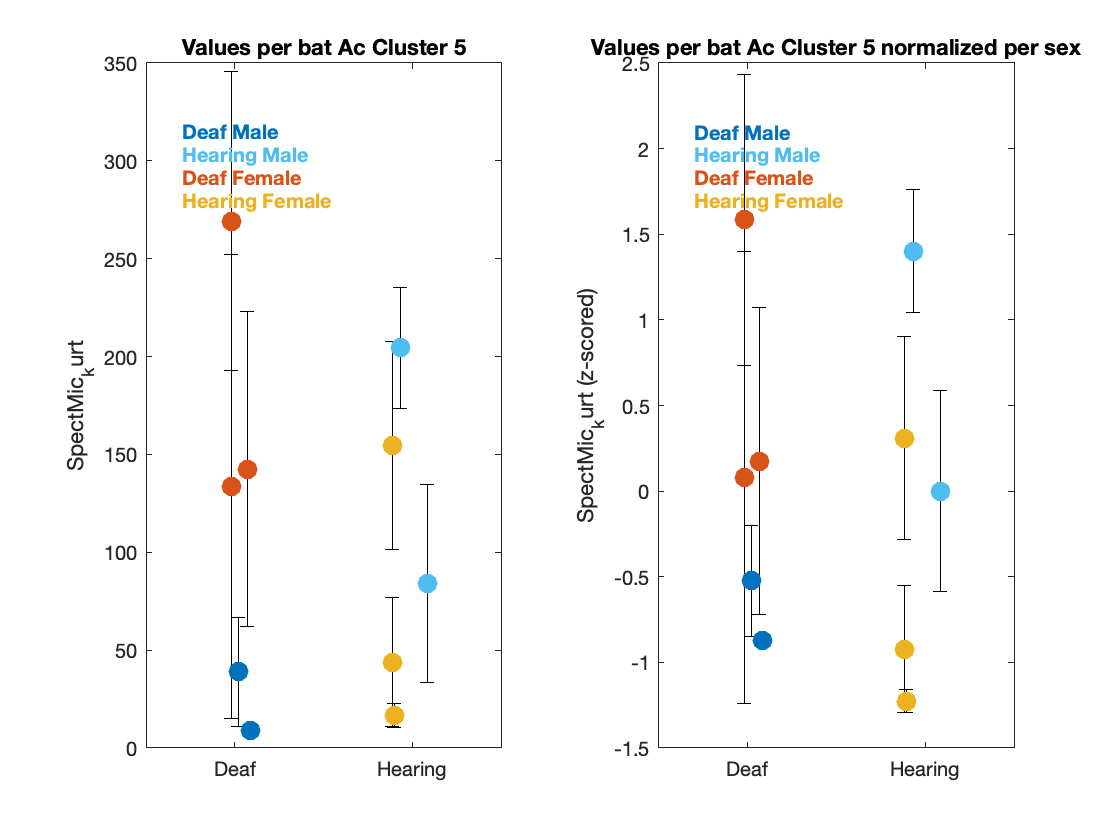

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q1Mic_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue   
    lmeR     4     6354.7    6370.1    -3173.3                                  
    lme      6     6347.9    6371.1    -3167.9    10.794    2          0.0045303


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue   
    lme2     5     6355.3    6374.6    -3172.7                                  
    lme      6     6347.9    6371.1    -3167.9    9.4468    1          0.0021152


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             353
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    6347.9    6371.1    -3167.9          6335.9  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat       DF     pValue         Lower      Upper 
    {'(Intercept)' }         6243.8     194.03      32.179    349    1.8169e-106     5862.2    6625.4
    {'Sex_F'       }         -80.37     459.94    -0.17474    349        0.86138    -984.97    824.23
    {'HorD_D'      }         1928.2     237.23      8.1279    349      7.675e-15     1461.6    2394.8
    {'Sex_F:HorD_D'}        -2653.2     569.05     -4.6625   

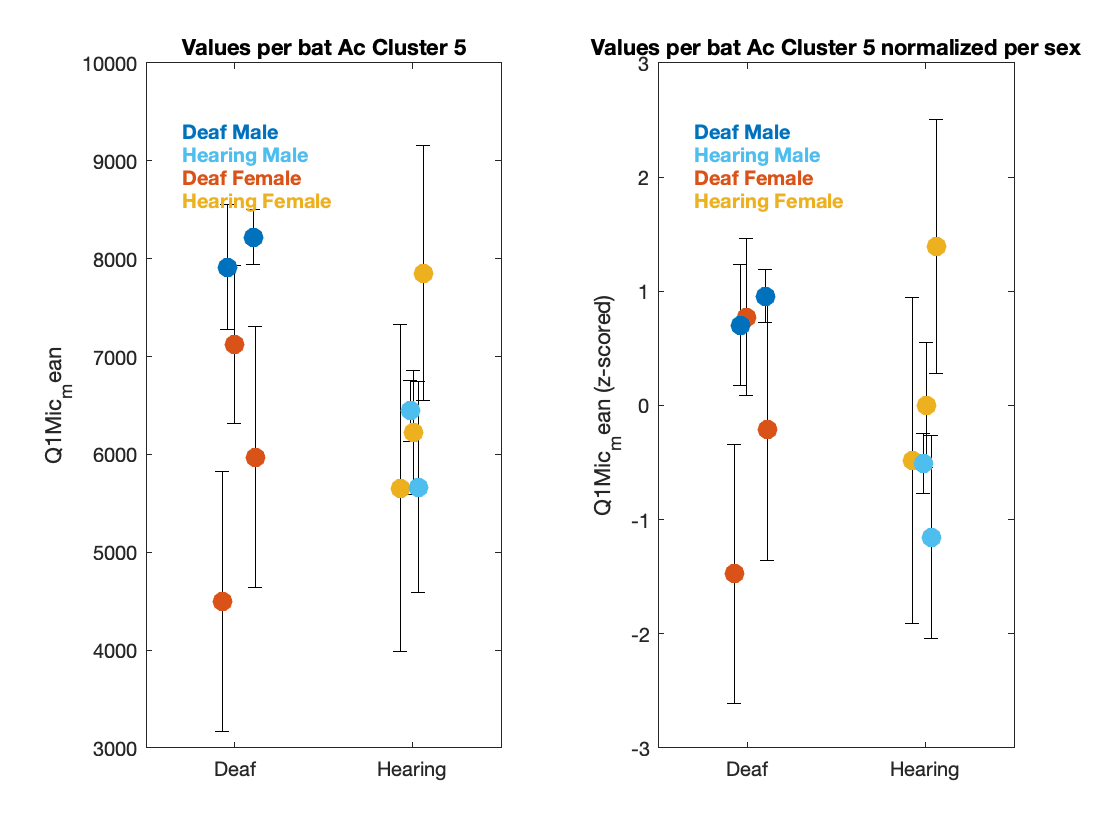

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 6----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    lmeR     4     3617.9    3632.6    -1804.9                                 
    lme      6     3613.3    3635.4    -1800.7    8.5392    2          0.013987


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    lme2     5     3617.7    3636.1    -1803.8                                 
    lme      6     3613.3    3635.4    -1800.7    6.3409    1          0.011798


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             294
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3613.3    3635.4    -1800.7          3601.3  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat      DF     pValue        Lower      Upper  
    {'(Intercept)' }         77.978     11.467     6.8001    290    5.9657e-11     55.408     100.55
    {'Sex_F'       }         9.7819      30.77    0.31791    290       0.75079    -50.778     70.342
    {'HorD_D'      }        -60.813     14.371    -4.2317    290    3.1149e-05    -89.098    -32.529
    {'Sex_F:HorD_D'}         99.788     39.415     2.5318    290 

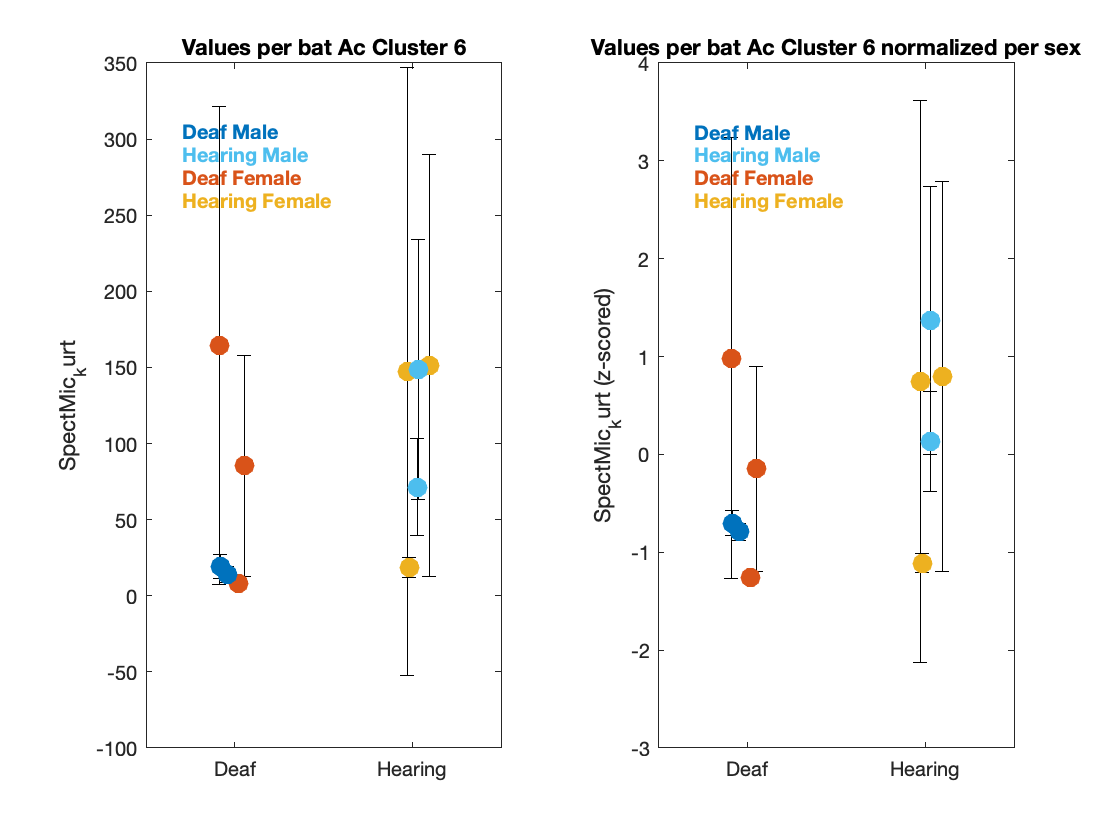

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q1Mic_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue
    lmeR     4     5303.6    5318.3    -2647.8                                
    lme      6     5308.8    5330.9    -2648.4    -1.1811    2          1     


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


% List of variables that were significant at the previous stage analysis
SigAcVars = logical((Pvalue_matrixFDR(:,1)<0.05) + ((Pvalue_matrixFDR(:,2)<0.05) + (Pvalue_matrixFDR(:,3)<0.05)));
AcVars = Tbl.Properties.VariableNames(6:end);
AcVars = AcVars(SigAcVars);

% All P-value of the tests are saved here for FDR correction in the end
Pvalue_matrix_Post_hoc = nan(length(AcVars),2,length(UCat));


for cc=1:length(UCat)
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------Acoustic Category %d----------------------------\n', UCat(cc))
    for vv=1:length(AcVars)
        fprintf(1,'-------------------------------------------------------------------------------\n')
        fprintf(1,'-------------------------------------------------------------------------------\n')
        fprintf(1, '*********************     LMEs on %s   ********************\n', AcVars{vv})
        AcVar = Tbl.(sprintf('%s',AcVars{vv}));
        if contains(AcVars{vv}, 'Mic')
            Ind = logical(MicAudioGood.*(AcousticClusters==UCat(cc)));
            Tbl_local = table(BatID(Ind), CallType(Ind), Sex(Ind),AcousticClusters(Ind),Deaf(Ind), AcVar(Ind), 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
        else
            Ind = AcousticClusters==UCat(cc);
            Tbl_local = table(BatID(Ind), CallType(Ind), Sex(Ind),AcousticClusters(Ind),Deaf(Ind), AcVar(Ind), 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
        end
        Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});

        % Full Model
        lme = fitlme(Tbl_local, 'AcVar ~ Sex * HorD + (1|BatID)');
        % Reduced model without deafening fixed effect
        lmeR = fitlme(Tbl_local, 'AcVar ~ Sex + (1|BatID)');
        TestLME_HD=compare(lmeR, lme)

        Pvalue_matrix_Post_hoc(vv,1,cc) = TestLME_HD.pValue(2);
        if TestLME_HD.pValue(2)<0.05
            lme2 = fitlme(Tbl_local, 'AcVar ~ Sex + HorD + (1|BatID)');
            TestLME_Int_HorD_Sex=compare(lme2, lme)
            Pvalue_matrix_Post_hoc(vv,2,cc) = TestLME_Int_HorD_Sex.pValue(2);
            lme

            % Nice plot
            AcVar_mean_pBat = nan(size(BatName));
            AcVar_se_pBat = nan(size(BatName));
            Col_local = nan(length(BatName),3);
            for bb=1:length(BatName)
                if contains(AcVars{vv}, 'Mic')
                    Ind = logical(MicAudioGood.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))));
                else
                    Ind = logical(AcousticClusters==UCat(cc) .* strcmp(BatID,num2str(BatName(bb))));
                end
                AcVar_mean_pBat(bb) = mean(AcVar(Ind), 'omitnan');
                AcVar_se_pBat(bb) = std(AcVar(Ind), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
                Col_local(bb,:) = UCSexDeaf(strcmp(USexDeaf, BatSexDeaf{bb}),:);
            end

            AcVar_Male_meanse(1) = mean(AcVar_mean_pBat(contains(BatSexDeaf, 'Male')));
            AcVar_Male_meanse(2) = std(AcVar_mean_pBat(contains(BatSexDeaf, 'Male')));
            AcVar_Female_meanse(1) = mean(AcVar_mean_pBat(contains(BatSexDeaf, 'Female')));
            AcVar_Female_meanse(2) = std(AcVar_mean_pBat(contains(BatSexDeaf, 'Female')));
            AcVar_meanse_pBat_sexnorm = nan(length(AcVar_mean_pBat),2);
            for bb=1:length(BatName)
                if contains(AcVars{vv}, 'Mic')
                    Ind = logical(MicAudioGood.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))));
                else
                    Ind = logical(AcousticClusters==UCat(cc) .* strcmp(BatID,num2str(BatName(bb))));
                end
                if contains(BatSexDeaf{bb}, 'Male')
                    AcVar_meanse_pBat_sexnorm(bb,1) = mean((AcVar(Ind) - AcVar_Male_meanse(1))./AcVar_Male_meanse(2), 'omitnan');
                    AcVar_meanse_pBat_sexnorm(bb,2) = std((AcVar(Ind) - AcVar_Male_meanse(1))./AcVar_Male_meanse(2), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
                elseif contains(BatSexDeaf{bb}, 'Female')
                    AcVar_meanse_pBat_sexnorm(bb,1) = mean((AcVar(Ind) - AcVar_Female_meanse(1))./AcVar_Female_meanse(2), 'omitnan');
                    AcVar_meanse_pBat_sexnorm(bb,2) = std((AcVar(Ind) - AcVar_Female_meanse(1))./AcVar_Female_meanse(2), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
                end
            end
            figure()
            tiledlayout(1,2)
            nexttile
            XHorD = ones(size(BatSexDeaf)) + (rand(size(BatSexDeaf))-0.5).*0.5;
            XHorD(contains(BatSexDeaf, 'Hearing')) = XHorD(contains(BatSexDeaf, 'Hearing'))+2;

            errorbar(XHorD,AcVar_mean_pBat, 2*AcVar_se_pBat, 2*AcVar_se_pBat, 'k.')
            hold on
            scatter(XHorD,AcVar_mean_pBat,100, Col_local, 'filled')
            ylabel(sprintf('%s', AcVars{vv}))
            XLim = [0 4];
            set(gca, 'XLim', XLim);
            YLim = get(gca, 'YLim');
            for ct=1:length(USexDeaf)
                text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
            end
            set(gca, 'XTick', [1 3],'XTickLabel', {'Deaf' 'Hearing'})
            hold off
            title(sprintf('Values per bat Ac Cluster %d', UCat(cc)))

            nexttile
            errorbar(XHorD,AcVar_meanse_pBat_sexnorm(:,1), 2*AcVar_meanse_pBat_sexnorm(:,2), 2*AcVar_meanse_pBat_sexnorm(:,2), 'k.')
            hold on
            scatter(XHorD,AcVar_meanse_pBat_sexnorm(:,1),100, Col_local, 'filled')
            ylabel(sprintf('%s (z-scored)', AcVars{vv}))
            XLim = [0 4];
            set(gca, 'XLim', XLim);
            YLim = get(gca, 'YLim');
            for ct=1:length(USexDeaf)
                text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
            end
            set(gca,'XTick', [1 3], 'XTickLabel', {'Deaf' 'Hearing'})
            hold off
            title(sprintf('Values per bat Ac Cluster %d normalized per sex', UCat(cc)))

        end
    end
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
end

**Now correct all comparisons for false discovery rate (True proba = p*(Num_comparisons-rank))**

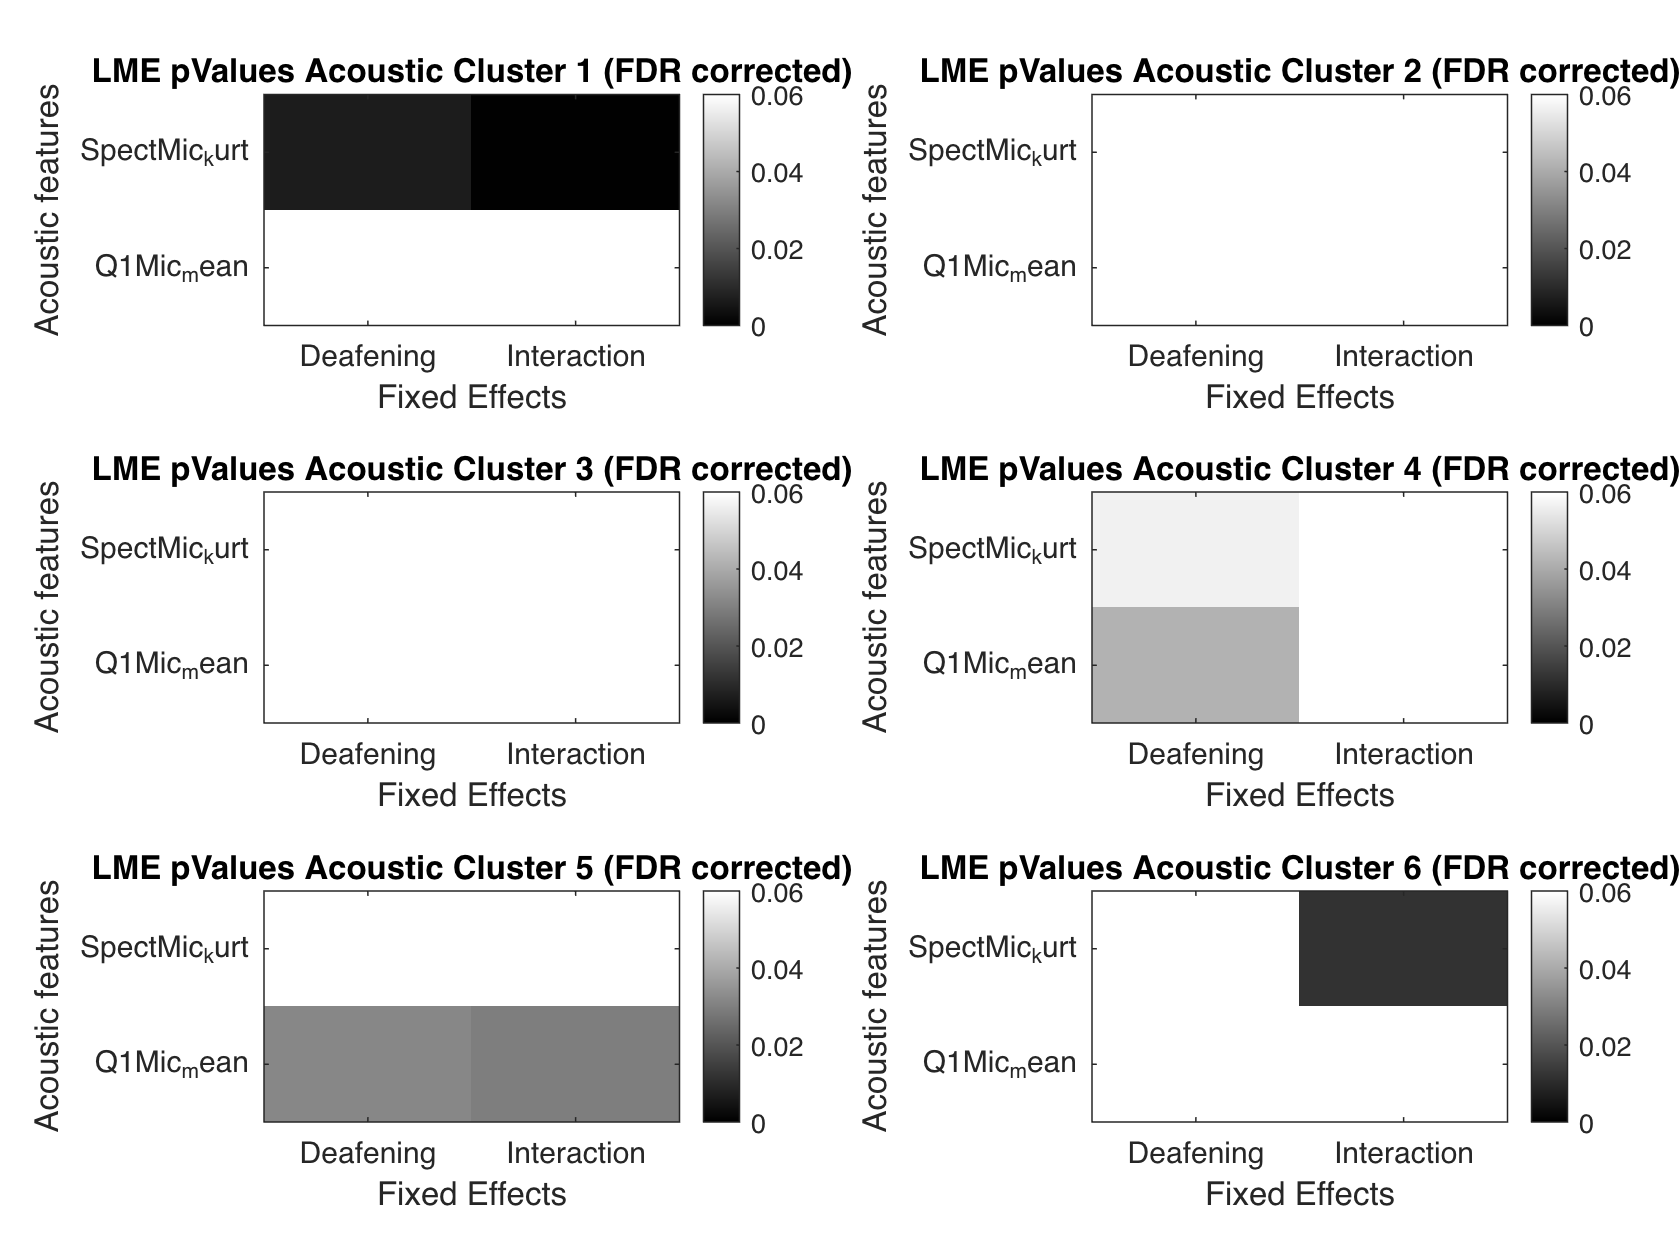

% Now correct that probability for False discovery rate (True proba =
% p*(Num_comparisons-rank))
Pvalue_vector = cell(1,length(UCat));
for cc=1:length(UCat)
    Pvalue_vector{cc} = [Pvalue_matrix_Post_hoc(:,1,cc)' Pvalue_matrix_Post_hoc(:,2,cc)'];
end
Pvalue_vector = [Pvalue_vector{:}];
NonNaNInd = ~isnan(Pvalue_vector);
[~,Ord]=sort(Pvalue_vector(NonNaNInd));
Ord(Ord==length(Ord)) = length(Ord)-1;
Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);

Pvalue_matrix_Post_hocFDR = nan(size(Pvalue_matrix_Post_hoc));
NVars = size(Pvalue_matrix_Post_hoc,1);
for cc=1:length(UCat)
    Pvalue_matrix_Post_hocFDR(:,:,cc) = [Pvalue_vectorFDR(((cc-1)*2*NVars) + (1:NVars))' Pvalue_vectorFDR(((cc-1)*2*NVars) + ((NVars+1):2*NVars))'];
end

figure()
tiledlayout(3,2)
for cc=1:length(UCat)
    nexttile
    Im = imagesc(Pvalue_matrix_Post_hocFDR(:,:,cc));
    colorbar()
    colormap(Im.Parent,'gray')
    Im.Parent.CLim = [0 0.06];
    set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
    set(gca, 'XTick', 1:2,'XTickLabel', {'Deafening' 'Interaction'})
    ylabel('Acoustic features')
    xlabel('Fixed Effects')
    title(sprintf('LME pValues Acoustic Cluster %d (FDR corrected)',cc))
end

## Bootstrap for the significance

Let's run the same analysis as before but shuffle the deafening labels accross bats

% List of variables
AcVars = Tbl.Properties.VariableNames(6:end);
NCK = perms(1:10);
NBoot = 200;
for bb=1:size(NCK,1)
    if prod(NCK(bb,:)==(1:10))
        NCK(bb,:)=[];
        break
    end
end
NCK = NCK(randperm(size(NCK,1)),:);% randomized permutations to increase diversity in the selected ones

% All P-value of the tests are saved here for FDR correction in the end

Pvalue_CellFDR_rand = cell(length(NBoot),1);
Pvalue_CellFDR_randInd = cell(length(NBoot),1);
parfor bb=1:NBoot
    Pvalue_matrix_rand = nan(length(AcVars),4);
    if ~rem(bb,20)
        fprintf(1, '\n\n*********************     Permutation %d/%d   ********************\n', bb, NBoot)
    end
    % Get the randomized vector ready for Deafness
    BatSexDeaf_rand = BatSexDeaf(NCK(bb,:));
    Pvalue_CellFDR_randInd{bb} = NCK(bb,:);
    Deaf_rand = cell(length(BatID),1);
    for bat = 1:length(BatName)
        if contains(BatSexDeaf_rand{bat}, 'Deaf')
            Deaf_rand(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        elseif contains(BatSexDeaf_rand{bat}, 'Hearing')
            Deaf_rand(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        else
            keyboard
        end
    end
    
    % Run the model with the 3 predictors
    % List of variables
    for vv=1:length(AcVars)
        if vv==1 && ~rem(bb,20)
            fprintf(1, ' LMEs on %s, ', AcVars{vv})
        elseif ~rem(bb,1)
            fprintf(1, '%s, ', AcVars{vv})
        end
        AcVar = Tbl.(sprintf('%s',AcVars{vv}));
        if contains(AcVars{vv}, 'Mic')
            Tbl_local = table(BatID(MicAudioGood), CallType(MicAudioGood), Sex(MicAudioGood),AcousticClusters(MicAudioGood),Deaf_rand(MicAudioGood), AcVar(MicAudioGood), 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
        else
            Tbl_local = table(BatID, CallType, Sex,AcousticClusters,Deaf_rand, AcVar, 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
        end
        Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});
        Tbl_local.AcousticClusters = categorical(Tbl_local.AcousticClusters);
        Tbl_local.Sex = categorical(Tbl_local.Sex);
        Tbl_local.BatID = categorical(Tbl_local.BatID);
    
        % Full Model
        try
            lme = fitlme(Tbl_local, 'AcVar ~ Sex * HorD * AcousticClusters+ (AcousticClusters|BatID)');
            % Reduced model without deafening fixed effect
            lmeR = fitlme(Tbl_local, 'AcVar ~ Sex * AcousticClusters + (AcousticClusters|BatID)');
            TestLME_HD=compare(lmeR, lme);
        
            Pvalue_matrix_rand(vv,1) = TestLME_HD.pValue(2);
            if TestLME_HD.pValue(2)<0.05
                lme;
                lme2 = fitlme(Tbl_local, 'AcVar ~ Sex * HorD + HorD * AcousticClusters + (AcousticClusters|BatID)');
                TestLME_Int3=compare(lme2, lme);
                Pvalue_matrix_rand(vv,2) = TestLME_Int3.pValue(2);
                lme3 = fitlme(Tbl_local, 'AcVar ~ Sex * HorD + AcousticClusters + (AcousticClusters|BatID)');
                TestLME_Int_HorD_AcCluster=compare(lme3, lme2);
                Pvalue_matrix_rand(vv,3) = TestLME_Int_HorD_AcCluster.pValue(2);
                lme4 = fitlme(Tbl_local, 'AcVar ~ Sex + HorD * AcousticClusters + (AcousticClusters|BatID)');
                TestLME_Int_HorD_Sex=compare(lme4, lme2);
                Pvalue_matrix_rand(vv,4) = TestLME_Int_HorD_Sex.pValue(2);
            end
        catch
            fprintf(1,'error with sequence:')
            NCK(bb,:)
            break
        end

    end
    % Now correct that probability for False discovery rate (True proba =
    % p*(Num_comparisons-rank))
    Pvalue_vector = [Pvalue_matrix_rand(:,1);Pvalue_matrix_rand(:,2);Pvalue_matrix_rand(:,3);Pvalue_matrix_rand(:,4)];
    NonNaNInd = ~isnan(Pvalue_vector);
    [~,Ord]=sort(Pvalue_vector(NonNaNInd));
    Ord(Ord==length(Ord)) = length(Ord)-1;
    Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
    Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);
    Pvalue_CellFDR_rand{bb} = [Pvalue_vectorFDR(1:size(Pvalue_matrix_rand,1)) Pvalue_vectorFDR((size(Pvalue_matrix_rand,1)+1) : 2*size(Pvalue_matrix_rand,1)) Pvalue_vectorFDR((2*size(Pvalue_matrix_rand,1)+1) : 3*size(Pvalue_matrix_rand,1)) Pvalue_vectorFDR((3*size(Pvalue_matrix_rand,1)+1) : end)];
end



*********************     Permutation 1/10   ********************


*********************     Permutation 2/10   ********************


*********************     Permutation 3/10   ********************


*********************     Permutation 4/10   ********************
 LMEs on Duration, RMS_mean, Sal_mean, F0_mean, Spect_mean, Spect_std, Spect_kurt, Spect_skew, Spect_ent, Time_mean, Time_std, Time_kurt, Time_skew, Time_ent, SpectralMean_mean, Q1_mean, Q2_mean, Q3_mean, SpectMic_mean, SpectMic_std, SpectMic_kurt, SpectMic_skew, SpectMic_ent, 

Pvalue_matrixFDR_rand = nan(length(AcVars),4, NBoot);
for bb=1:NBoot
    Pvalue_matrixFDR_rand(:,:,bb) = Pvalue_CellFDR_rand{bb};
end
save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls.mat'), 'Pvalue_matrixFDR_rand','Pvalue_CellFDR_randInd','-append')

**Now plot the probability of random discovery**

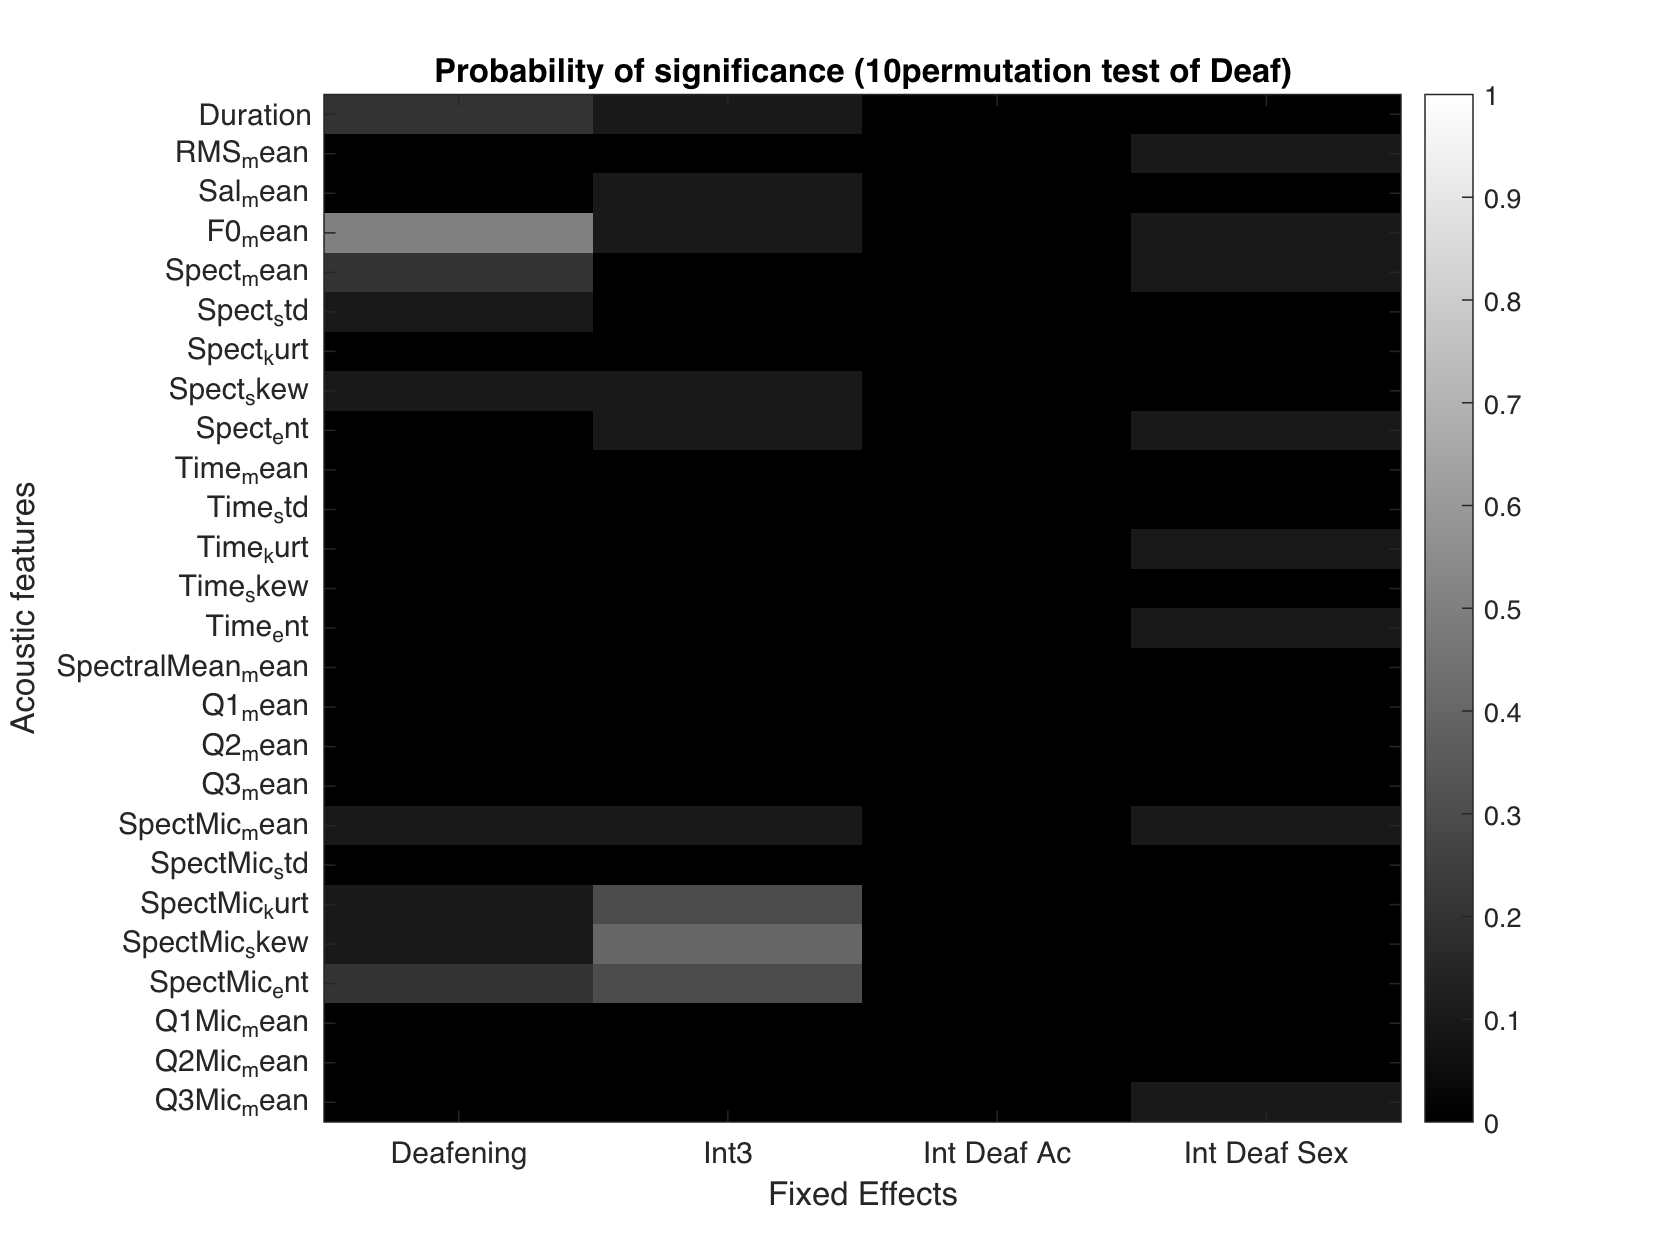

figure()

Im = imagesc(sum(Pvalue_matrixFDR_rand<0.01,3)./NBoot);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 1];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1:4,'XTickLabel', {'Deafening' 'Int3' 'Int Deaf Ac' 'Int Deaf Sex'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title(sprintf('Probability of significance (%dpermutation test of Deaf)', NBoot))


    % run the models within each acoustic category with Sex and Deaf


